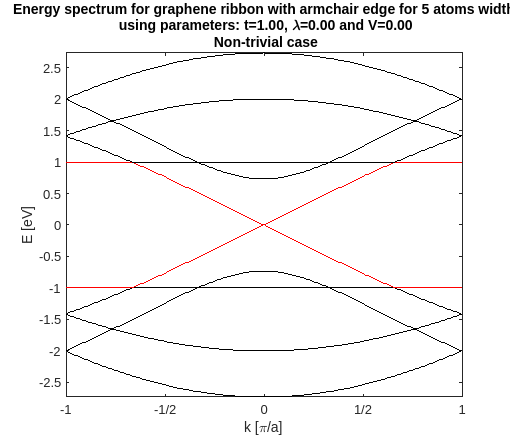

%initializing parameters & Bravais vectors
a1 = 0.5*[-sqrt(3),3];
a2 = 0.5*[sqrt(3),3];
a = 3*norm(a1); %unit cell width
%Generating Hamiltonian
        %Parameters:
            t = 1;
            L = 0;
            V = 0;
        %
figure('Renderer', 'painters', 'Position', [200 100 800 700]);
filename = 'ChangingL_V=0,2.gif';
grid = 100;
K = -pi/a:pi/grid/a:pi/a;

n = 5; %width in number of atoms
%for L=-0.2:0.01:0.2
N = 2*n; %number of atoms in unit cell

E = zeros(length(K),N);
    for g = 1:length(K)
        k = K(g);
        u = exp(1i*k*a); %u is phase going right
        
            H_NN  = zeros(N,N);
            H_NNN = zeros(N,N);            
        
        for ii=1:n-1
          %Nearest neighbours
            H_NN(ii,ii+1)     = t;
            H_NN(N-ii+1,N-ii) = t;
            if(mod(ii,2)==0) %even numbers
                H_NN(ii,N-ii+1) = t; %2->13 or for even 2->15
                H_NN(ii,ii) = -V;
            else %odd
                H_NN(ii,N-ii+1) = t*conj(u); %1->14_ or 1->16_
                H_NN(ii,ii) = V;
            end
            
          %Next Nearest Neighbours
            if(ii <= n-2)
                H_NNN(ii,ii+2)       = -((-1)^ii)*1i*L; %1->3
                H_NNN(N-ii+1,N-ii-1) =  ((-1)^ii)*1i*L; %14->12
                H_NNN(ii,N-ii)       =  ((-1)^ii)*1i*L*(1+conj(u)); %1->13,13_
                H_NNN(N-ii+1,ii+1)   = -((-1)^ii)*1i*L*(1+u); %14->2,2+,...if i=1 then +
            end
        end
       %Edge points
        if(mod(n,2)==1) %odd width
            H_NN(n,n+1)    = t*conj(u);
            H_NNN(n-1,n+1) = 1i*L*(1+conj(u));
        else %even width
            H_NN(n,n+1)    = t;
            H_NNN(n-1,n+1) = -1i*L*(1+conj(u));
        end
        
        H = H_NN + H_NNN;
        H = H + H';
        E(g,:) = eig(H);
    end
    %%
    %Plotting energy
    for ii=1:N
        if((ii==N/2) || (ii==N/2+1))
            plot(K,E(:,ii),'r-');
        else
            plot(K,E(:,ii),'k-');
        end
        hold on
    end
    drawnow
    title(sprintf('Energy spectrum for graphene ribbon with armchair edge for %0.0f atoms width\n using parameters: t=%0.2f, \\lambda=%0.2f and V=%0.2f\n Non-trivial case',N/2,t,L,V)); drawnow
    xlabel(sprintf('k [\\pi/a]')); 
    ylabel(sprintf('E [eV]')); 
    xticks([-pi -pi/2 0 pi/2 pi]/a); 
    xticklabels({'-1','-1/2','0','1/2','1'});
    axis([min(K) max(K) min(E(:,1)) max(E(:,N))]); drawnow

    hold off